# DAFx 2022 Tutorial: Source-Filter Modeling

## Preliminaries

Run `prelim` script to perform preliminary tasks. Add base folder and all subfolders to the Matlab path. Load definition of colors for plotting.

prelim;

### Live Script Flags

These flags control the general behavior of the script, such as enabling/disabling automatically playing the sounds.

playsndflag = true;

## Load Sound File

[sndfile,fpath] = uigetfile('audio/*.wav');

Get file path, name, and extension

[~,fname,fext] = fileparts(sndfile);

Clean up sound file name

sndname = strrep(fname,'_',' ');

### Read Sound File

[wav,fs] = audioread(sndfile);

## Source-Filter Analysis Parameters

### Spectral AnalysisAnalysis Window

winflag = 6;

#### Causality of First Window

The text flag `CAUSALFLAG` controls the causality of the first window. The option `CAUSALFLAG = "CAUSAL" `uses a ***causal*** first analysis window, placing it totally *inside* the waveform to be analyzed. The option `CAUSALFLAG = "NON" `uses a ***non-causal*** first analysis window`,` placing its center at the first sample of the waveform to be analyzed. Finally, the option `CAUSALFLAG = "ANTI"` uses an ***anti-causal*** first analysis window, placing it totally *outside* the waveform to be analyzed.

causalflag = "non";

#### Normalize Analysis Window

normflag = true;

#### Zero-Phase Window

zphflag = true;

## Spectral Envelope Estimation

### Cepstral Window

cepswinflag = 6;

### Spectral Envelope Parameters

specenvflag = "lpc";

### True Envelope Estimation Error Threshold

maxdiff =  0.05;

#### Maximum Number of Iterations for True Envelope Estimation

maxit = 100;

#### Log Magnitude Spectrum

The flag `LOGFLAG` determines the logarithm used in the calculation of the cepstrum. Usually, $20 \log_{10}x=x\,\mathrm{dB\,power}$.

logflag = "dbp";

### Optimization Step

The logical flag `STEPFLAG control the optimization steps`. Set `STEPFLAG = TRUE` to optimize estimation and `STEPFLAG = FALSE` to skip optimization.

stepflag = true;

### Downsample Spectrum

dsflag = false;

### Positive Spectrum

posspecflag = false;

### Spectral Energy

nrgflag = false;

### Biased Autocorrelation

biasflag = false;

### Linear Prediction Estimation

#### Levinson-Durbin Recursion

The logical flag `LEVFLAG` controls if the normal equations are solved with the Levinson-Durbin recursion or matrix inversion. `LEVFLAG = TRUE` uses Levinson-Durbin recursion and `LEVFLAG = FALSE` uses matrix inversion.

levflag = true;

### Variable Parameters

Estimate time-varying fundamental frequency `f0` between `f0min` and `f0max.`

f0min = 75;
f0max = 500;
f0 = swipep_mod(wav,fs,[f0min f0max],1000/fs,[],1/20,0.5,0.2);

Average of `f0`

ref0 = tools.f0.reference_f0(f0);

### Short-Time Fourier Transform

Frame size $M=nT_0$

nT0 = 4;

### Oversampling Factor

osfac = 2;

### Frame size

Calculate the length of the frame of the STFT in samples

framelen = tools.dsp.framesize(f0,fs,nT0);

### Frame Overlap

overlap = 0.5;

### Hop size

hop = tools.dsp.hopsize(framelen,overlap);

### Size of the FFT

Size of the FFT $N$

nfft = tools.dsp.fftsize(framelen,osfac);

### Order of the Spectral Envelope

orderflag = false;

if orderflag
    order = spec_env_order(ref0,fs,cepswinflag,specenvflag);
else
    order = 20;
end

## Source-Filter Analysis

[source,filter_coeff,err,lp_coeff,order,center_frame,nsample,nframe,nchannel,spec_env_curve] = source_filter_analysis(wav,framelen,hop,nfft,fs,...
    winflag,causalflag,normflag,zphflag,specenvflag,...
    cepswinflag,ref0,order,biasflag,levflag,maxit,maxdiff,logflag,stepflag,dsflag,posspecflag,nrgflag);

Source-Filter Analysis


## Figure Data and Parameters

Make spectra for figures and set parameters for plots.

### Short-Time Fourier Transform of Original Waveform

[fftframe_wav,center_frame,nsample,nframe,nchannel,dc] = tools.stft.stft(wav,framelen,hop,nfft,winflag,causalflag,normflag,zphflag);

### Short-Time Fourier Transform of Source

fftframe_source = tools.stft.stft(source,framelen,hop,nfft,winflag,causalflag,normflag,zphflag);

### Plot Parameters

Flag for log magnitude spectrum of plot.

logplotflag = "dbp";

Flag to select only positive frequencies or full frequency range with negative and positive frequencies.

posfreqplotflag = true;
if posfreqplotflag
    freq_plot = tools.plot.mkfreq(nfft,fs)/1000;
    fmax = fs/2000;
else
    freq_plot = tools.plot.mkfreq(nfft,fs,'full')/1000;
    fmax = fs/1000;
end

iplot = floor(nframe/2);
ichannel = 1;

## Plot Spectral Envelope

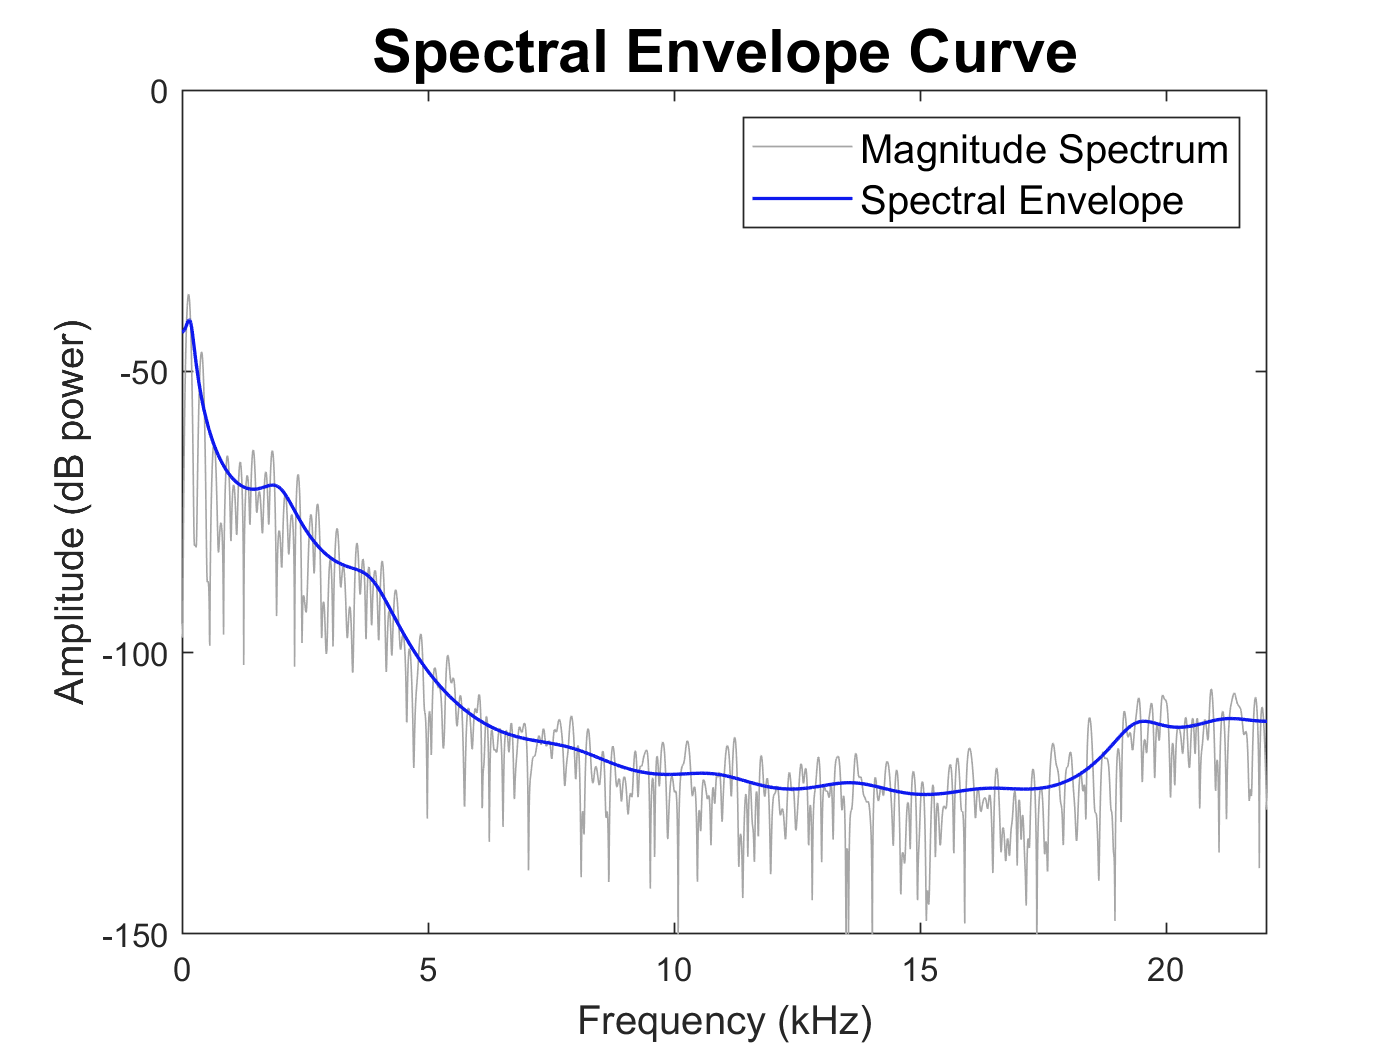

plot(freq_plot,tools.fft2.fft2log_mag_spec(fftframe_wav(:,iplot,ichannel),nfft,logplotflag,posfreqplotflag),'Color',col.g)
hold on
plot(freq_plot,tools.fft2.fft2log_mag_spec(spec_env_curve(:,iplot,ichannel),nfft,logplotflag,posfreqplotflag),'Color',col.db,'LineWidth',1)
hold off
legend({'Magnitude Spectrum','Spectral Envelope'},'FontSize',12)
title('Spectral Envelope Curve','FontSize',18)
xlabel('Frequency (kHz)','FontSize',12)
ylabel('Amplitude (dB power)','FontSize',12)
xlim([0 fmax])
ylim([-150 0])

### Plot Source

The source signal is the original waveform inverse-filtered with the spectral envelope. The effect of inverse-filtering is "whitening" the spectrum.

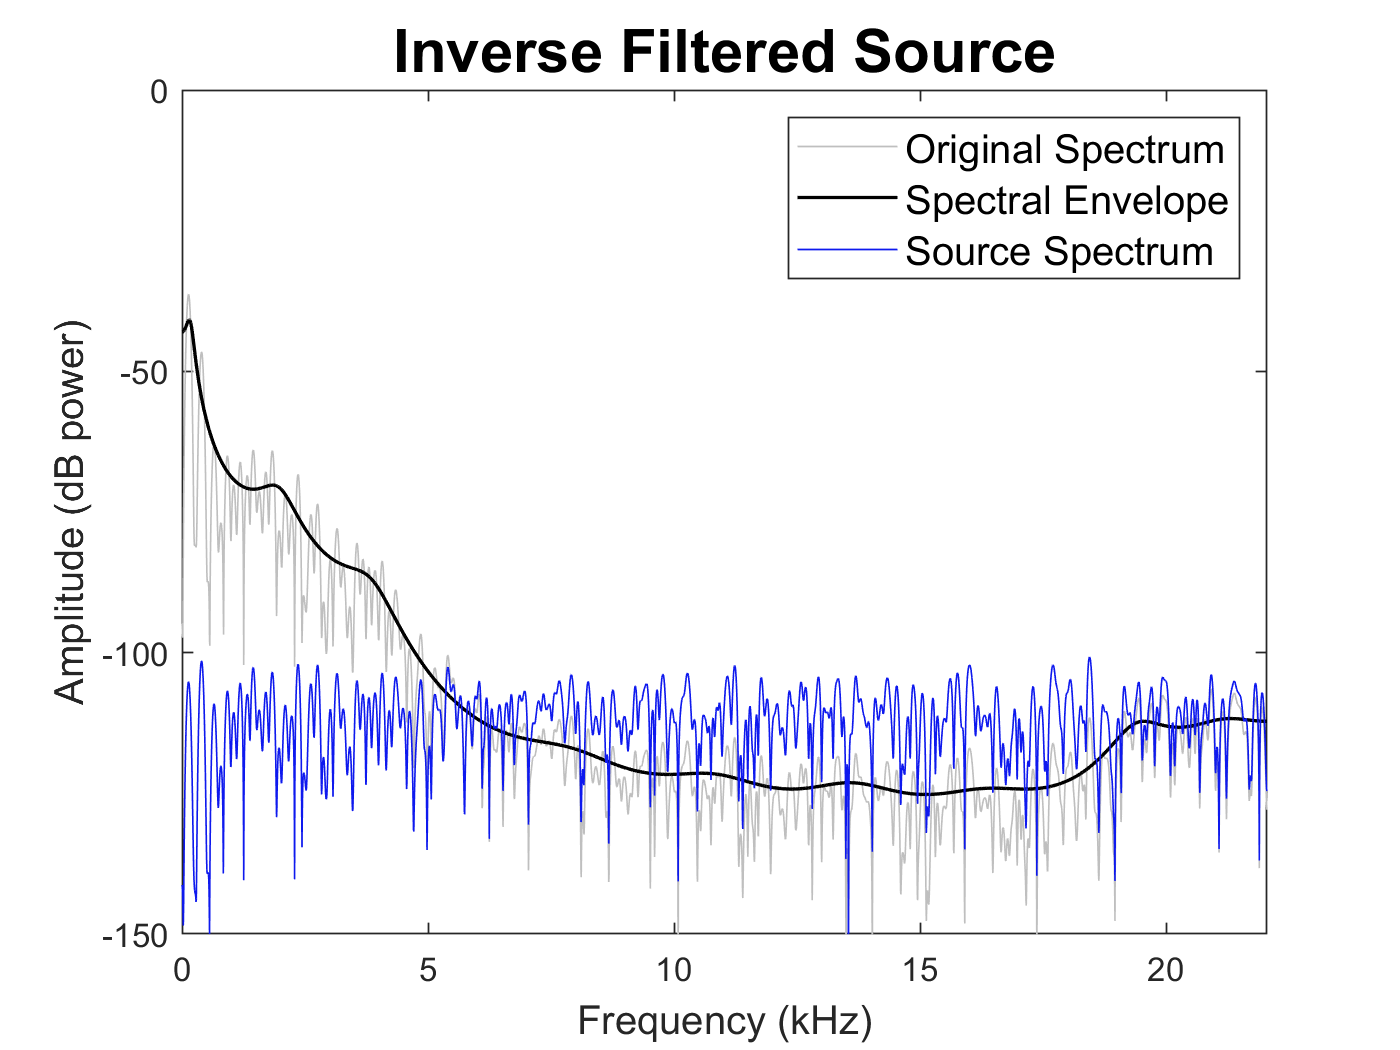

plot(freq_plot,tools.fft2.fft2log_mag_spec(fftframe_wav(:,iplot,ichannel),nfft,logplotflag,posfreqplotflag),'Color',col.ht)
hold on
plot(freq_plot,tools.fft2.fft2log_mag_spec(spec_env_curve(:,iplot,ichannel),nfft,logplotflag,posfreqplotflag),'Color',col.b,'LineWidth',1)
plot(freq_plot,tools.fft2.fft2log_mag_spec(fftframe_source(:,iplot,ichannel),nfft,logplotflag,posfreqplotflag),'Color',col.db)
hold off
legend({'Original Spectrum','Spectral Envelope','Source Spectrum'},'FontSize',12)
title('Inverse Filtered Source','FontSize',18)
xlabel('Frequency (kHz)','FontSize',12)
ylabel('Amplitude (dB power)','FontSize',12)
xlim([0 fs/2000])
ylim([-150 0])

## Source-Filter Resynthesis

### Filter Source or External Input

extsigflag = false;

### Inverse Filter Source

source_filt = source_filter_resynthesis(source,lp_coeff,order,framelen,hop,nsample,nchannel,causalflag,extsigflag,err,center_frame);

Source-Filter Resynthesis


### Residual from Source-Filter Resynthesis

Calculate the residual from sinusoidal analysis

residual = wav - source_filt;

#### Signal-to-Resynthesis Energy Ratio (SRER)

Calculate the signal-to-resynthesis energy ratio for the model

srer_db = tools.wav.srer(wav,residual);

#### Signal-to-Source Energy Ratio (SSER)

sser_db = tools.wav.srer(wav,source);

## Plot Source-Filter Model

### Figure Parameters

time_samples = tools.plot.mktime(nsample,fs);

### Plot Original vs Source-Filter Model

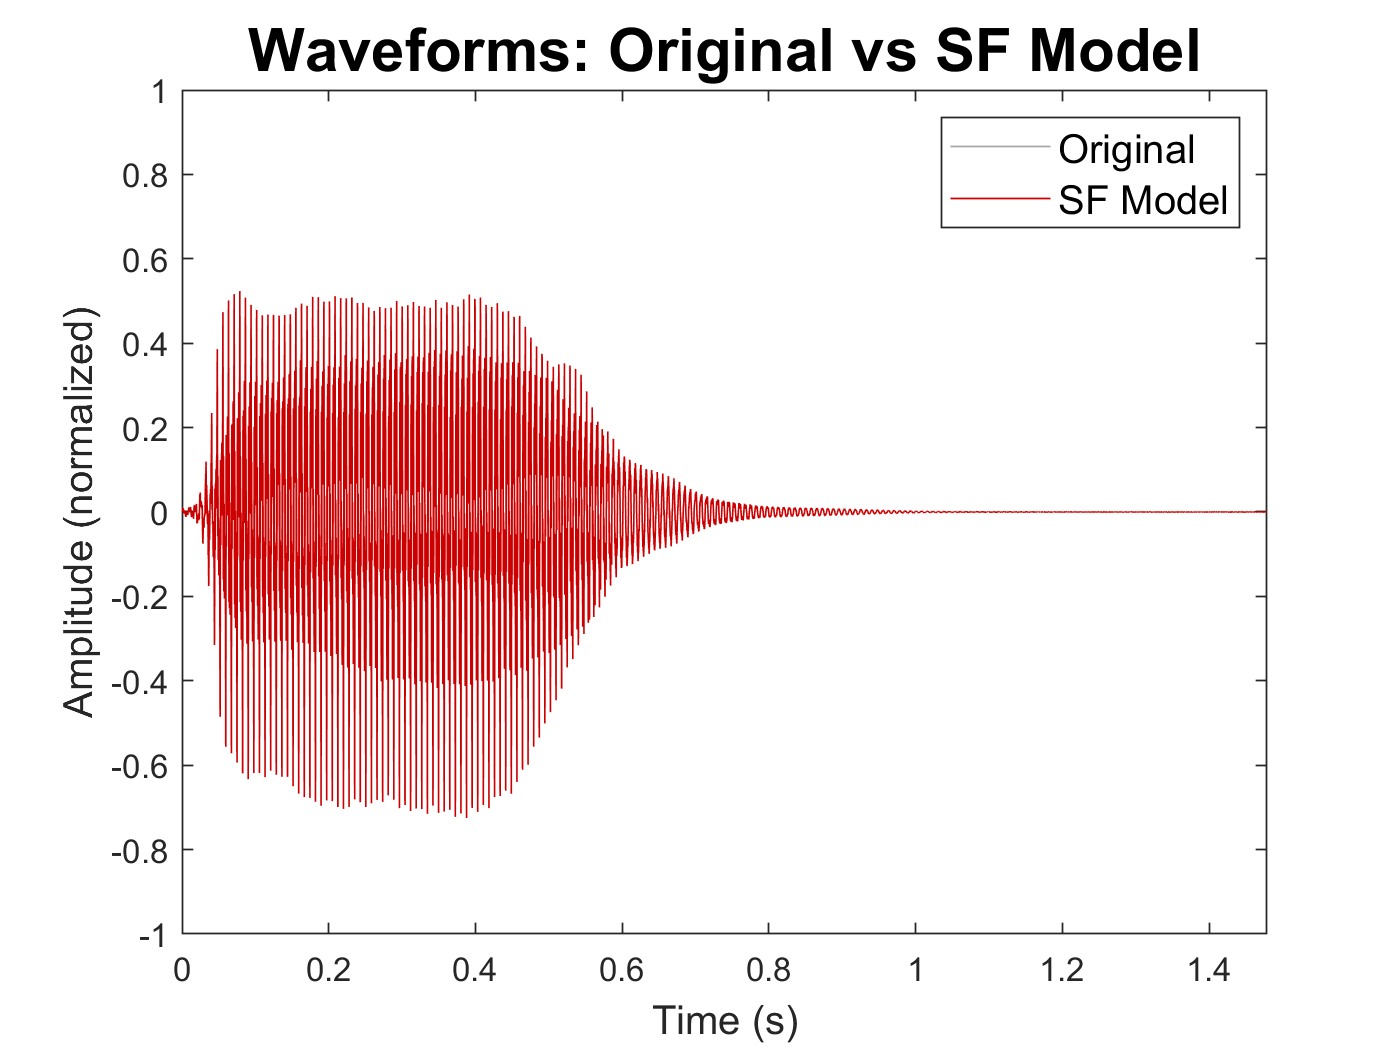

plot(time_samples,wav(:,ichannel),'Color',col.g)
hold on
plot(time_samples,source_filt(:,ichannel),'Color',col.br)
hold off
legend({'Original','SF Model'},'FontSize',12)
title('Waveforms: Original vs SF Model','FontSize',18)
xlabel('Time (s)','FontSize',12)
ylabel('Amplitude (normalized)','FontSize',12)
xlim([time_samples(1) time_samples(end)])
ylim([-1 1])

### Plot SF Model vs Source

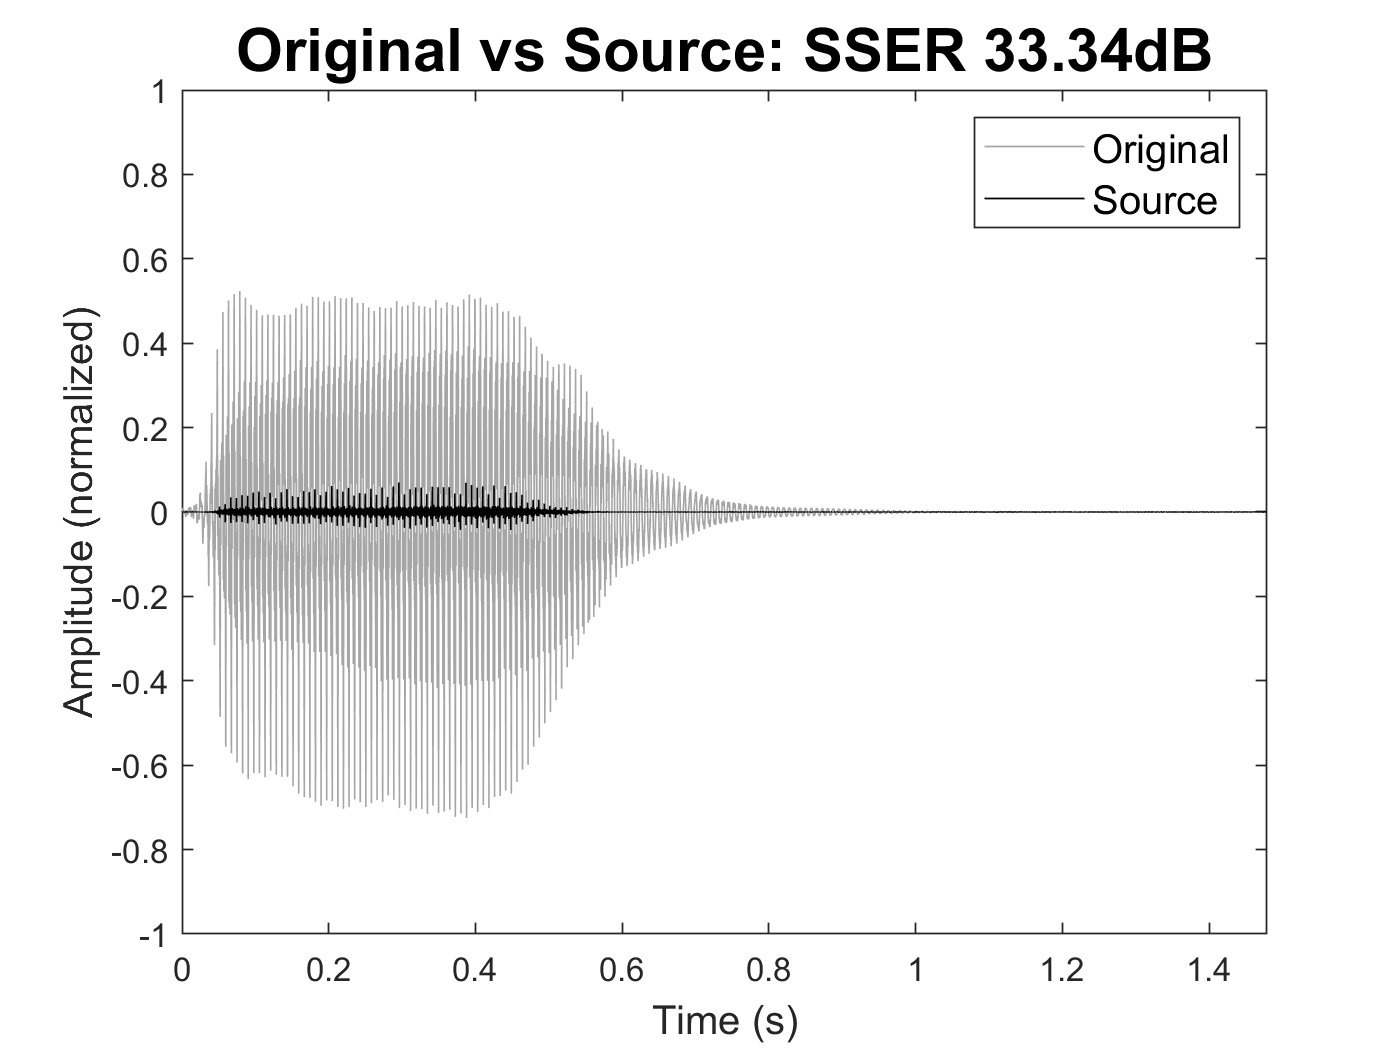

plot(time_samples,source_filt(:,ichannel),'Color',col.g)
hold on
plot(time_samples,source(:,ichannel),'Color',col.b)
hold off
legend({'Original','Source'},'FontSize',12)
title(sprintf('Original vs Source: SSER %2.2fdB',sser_db),'FontSize',18)
xlabel('Time (s)','FontSize',12)
ylabel('Amplitude (normalized)','FontSize',12)
xlim([time_samples(1) time_samples(end)])
ylim([-1 1])

### Plot Original vs Residual

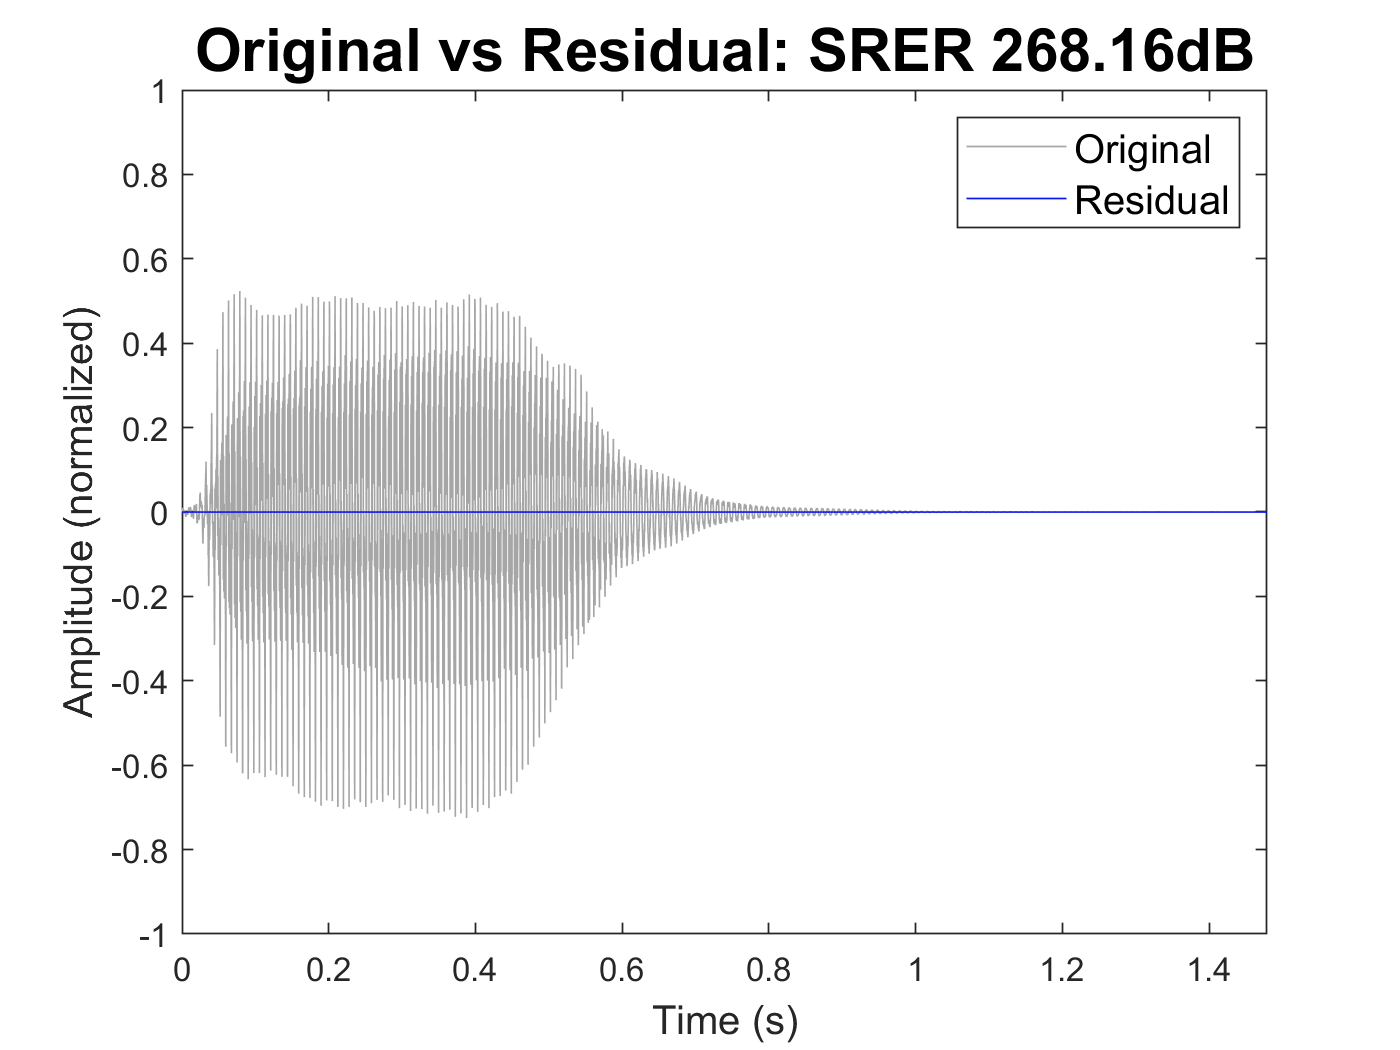

plot(time_samples,wav(:,ichannel),'Color',col.g)
hold on
plot(time_samples,residual,'Color',col.db)
hold off
legend({'Original','Residual'},'FontSize',12)
title(sprintf('Original vs Residual: SRER %2.2fdB',srer_db),'FontSize',18)
xlabel('Time (s)','FontSize',12)
ylabel('Amplitude (normalized)','FontSize',12)
xlim([time_samples(1) time_samples(end)])
ylim([-1 1])

## Play Original Sound

if playsndflag
    sound(wav,fs)
    pause(nsample/fs)
end

## Play Source-Filter Model

if playsndflag
    sound(source_filt,fs)
    pause(nsample/fs)
end

## Play Source

if playsndflag
    sound(source,fs)
    pause(nsample/fs)
end

Normalize modeling residual and play.

if playsndflag
    sound(tools.wav.normdb(source,-16,'rms'),fs)
end

## Play Modeling Residual

if playsndflag
    sound(residual,fs)
    pause(nsample/fs)
end

Normalize modeling residual and play.

if playsndflag
    sound(tools.wav.normdb(residual,-16,'rms'),fs)
end

## Acknowledgements

This project has received funding from the European Union’s Horizon 2020 research and innovation programme under the Marie Sklodowska-Curie grant agreement No 831852 (MORPH)